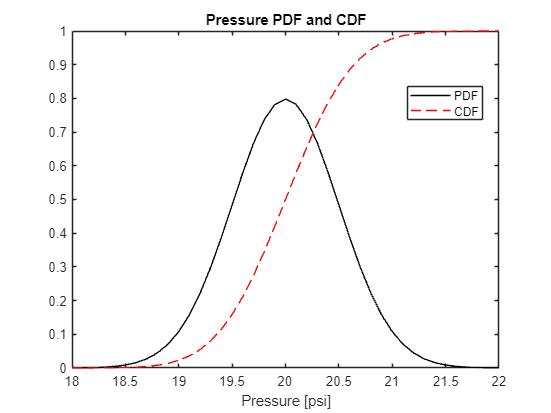

%% Experimental Methods HW #1 Dan Lawson (git hub test)

%% Problem 2 Confidence Interval

% Plot both PDF and CDF on the same graph given mean and sigma
P_bar = 20;

sigma = 0.5;

x = 18:0.1:22;

z = normpdf(x, P_bar, sigma);
N = normcdf(x, P_bar, sigma);

figure
plot(x,z,'-k'); hold on;
plot(x,N,'--r');
xlabel('Pressure [psi]')
legend(["PDF","CDF"],Location="best")
title('Pressure PDF and CDF')


% Probability (%) measured value is less than 19.2 psi?

Prob_b = 100*normcdf(19.2, 20, 0.5)

Prob_b = 5.4799


% Probability (%) measured value is between 19.6 and 20.9 psi?

Prob_c = 100*(normcdf(20.9, 20, 0.5) - normcdf(19.6, 20, 0.5))

Prob_c = 75.2214


% Probability (%) measured value is larger than 20.5 psi?

Prob_d = 100*(1 - normcdf(20.5, 20, 0.5))

Prob_d = 15.8655

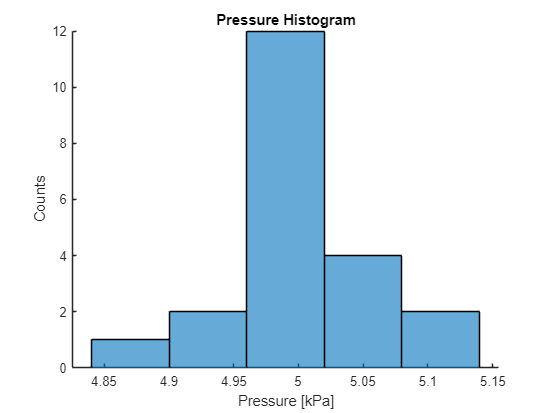


%% Problem 3 Sample Data

% Plot Meaningful histograms for the given prssure and temp data

P = [4.95, 4.87, 5.1, 4.99, 5.06, 5.09, 4.95, 5.01, 4.98, 5.01, 4.96, 4.99, 5.00, 5.05, 5.00, 5.02, 5.01, 5.06, 4.99, 5.01, 4.98];
T = [21.2, 21.3, 21.0, 21.2, 21.5, 20.9, 21.2, 21.4, 21.1, 21.2, 21.4, 21.1, 21.4, 20.9, 21.5, 21.2, 21.6, 21.1, 20.8, 20.7, 20.9];

figure
hold on
P_h = histogram(P, 5);
title('Pressure Histogram')
xlabel('Pressure [kPa]')
ylabel('Counts')

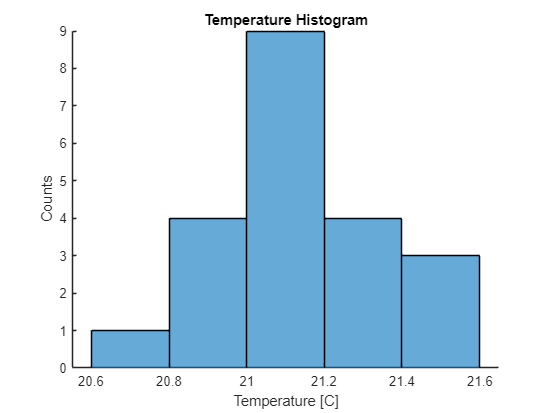


figure
hold on
T_h = histogram(T, 5);
title('Temperature Histogram')
xlabel('Temperature [C]')
ylabel('Counts')


% Determine Means and Standard Deviations for data sets P and T

P_mean = mean(P)

P_mean = 5.0038

P_sigma = std(P)

P_sigma = 0.0514


T_mean = mean(T)

T_mean = 21.1714

T_sigma = std(T)

T_sigma = 0.2452



% Determine the best estimate of means for the presssure and temperature
% data at 50% and 90% confidence intervals

conf = 0.50;
a = 1 - ((1 - conf)/2);
tdist = tinv(a, length(P)-1);
P_err_50 = (tdist*P_sigma)/sqrt(length(P));
T_err_50 = (tdist*T_sigma)/sqrt(length(T));

fprintf('3) Pressure mean at 50%% confidence %g +/- %g',round(P_mean,3), round(P_err_50,2))

3) Pressure mean at 50% confidence 5.004 +/- 0.01

fprintf('3) Temperature mean at 50%% confidence %g +/- %g',round(T_mean,2), round(T_err_50,2))

3) Temperature mean at 50% confidence 21.17 +/- 0.04


conf = 0.90;
a = 1 - ((1 - conf)/2);
tdist = tinv(a, length(P)-1);
P_err_90 = (tdist*P_sigma)/sqrt(length(P));
T_err_90 = (tdist*T_sigma)/sqrt(length(T));

fprintf('3) Pressure mean at 90%% confidence %g +/- %g',round(P_mean,2), round(P_err_90,2))

3) Pressure mean at 90% confidence 5 +/- 0.02

fprintf('3) Temperature mean at 90%% confidence %g +/- %g',round(T_mean,1), round(T_err_90,2))

3) Temperature mean at 90% confidence 21.2 +/- 0.09


% Problem 4 

% Determine the best estimate of the mean for the given temperature data at 90%
% and 95% confidence intervals

T = [10.12, 10.07, 10.59, 9.96, 9.47];
T_mean = mean(T);
T_sigma = std(T);

conf = 0.90;
a = 1 - ((1 - conf)/2);
tdist = tinv(a, length(T)-1);
T_err_90 = (tdist*T_sigma)/sqrt(length(T));

fprintf('4) Temperature mean at 90%% confidence %g +/- %g',round(T_mean,2), round(T_err_90,2))

4) Temperature mean at 90% confidence 10.04 +/- 0.38


conf = 0.95;
a = 1 - ((1 - conf)/2);
tdist = tinv(a, length(T)-1);
T_err_95 = (tdist*T_sigma)/sqrt(length(T));

fprintf('4) Temperature mean at 95%% confidence %g +/- %g',round(T_mean,2), round(T_err_95,2))

4) Temperature mean at 95% confidence 10.04 +/- 0.5


T = [10.12, 10.07, 10.59, 9.96, 9.47, 9.98, 9.99, 9.63, 10.07, 10.24];

T_mean = mean(T);
T_sigma = std(T);

conf = 0.90;
a = 1 - ((1 - conf)/2);
tdist = tinv(a, length(T)-1);
T_err_90 = (tdist*T_sigma)/sqrt(length(T));

fprintf('4) Temperature mean at 90%% confidence with extra data %g +/- %g',round(T_mean,2), round(T_err_90,2))

4) Temperature mean at 90% confidence with extra data 10.01 +/- 0.18


conf = 0.95;
a = 1 - ((1 - conf)/2);
tdist = tinv(a, length(T)-1);
T_err_95 = (tdist*T_sigma)/sqrt(length(T));

fprintf('4) Temperature mean at 95%% confidence with extra data %g +/- %g',round(T_mean,2), round(T_err_95,2))

4) Temperature mean at 95% confidence with extra data 10.01 +/- 0.22